%% simu2_2 运动点目标的回波仿真
%% 参数初始化
PRF = 2e3; % 脉冲重复频率
PRI = 1/PRF; % 脉冲重复间隔
f0 = 10e6;
fs = 100e6; % 采样率
Bw = 70e6; % 带宽
tp = 9e-6; % 脉宽
K = Bw / tp; % 调制斜率
c = 3e8;
% N = 6/60 * PRF; % 根据时长(s)来确定脉冲个数
N = 30; % 脉冲数定为30个 
smp_mc = 10; % 单次采样时间的比脉宽
t = 0:1/fs:smp_mc*tp + tp; % 单次采样的时间长度为21个脉宽 (一个PRI可以包含100个脉冲，占空比为1%)
N_smp = length(t); % 采样点个数
Rmax = smp_mc * tp * c / 2; % 本程序可以探测的最远距离！！ 实际应该是 1/2 * c * PRI


% 目标参数
N_tgt = 1; 
R_tgt = [1000, 1100, 1500]; % 目标距离
V = [-500, 0, 0]; % 目标速度
RCS = [1, 2, 4]; % RCS

%% 生成回波矩阵（二维矩阵）
sig_r = zeros(N, N_smp); % 纵坐标脉冲数目 横坐标为采样时间
for i_puls = 1:N
    ta = (i_puls - 1) * PRI;
    sri = 0;
    for i_tgt = 1:N_tgt
        t_delay = 2*(R_tgt(i_tgt) - V(i_tgt).*(ta + t)) / c; % 计算时延
        Tp = c*tp/(c-V(i_tgt));
        srj = sqrt(RCS(i_tgt)).*rectpuls(t - t_delay - Tp/2, Tp).*exp(1j * pi * K.*(t - t_delay - Tp/2).^2); % 这里直接生成基带信号 可以添加高频信号后进行滤波
        sri = sri + srj;
    end
    sig_r(i_puls, :) = sri;
end
t_y = (1:N)/PRF;
R_x = c*t/2; % 横坐标



## 观察回波信号

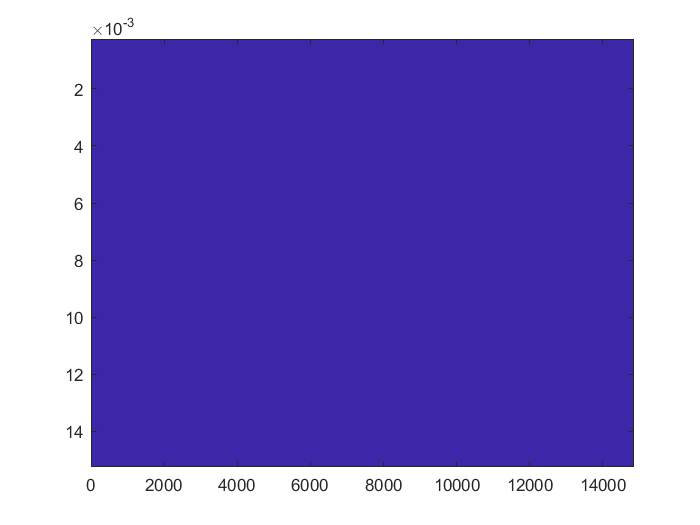

figure(1)
image(R_x, t_y, abs(sig_r));

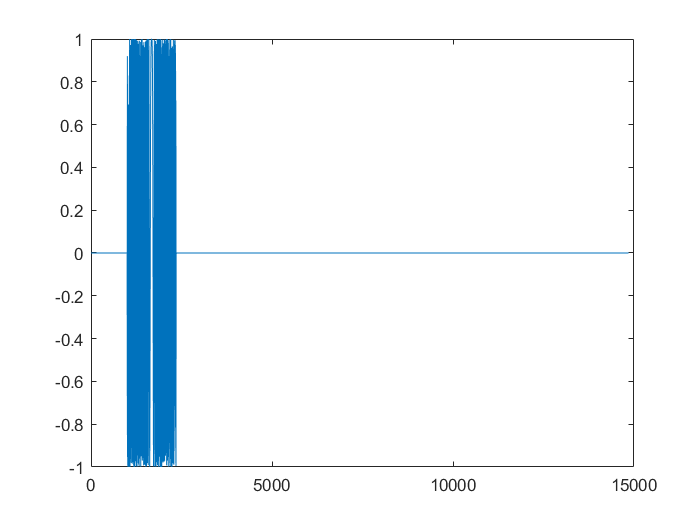

figure(2)
plot(R_x, real(sig_r(1, :))); % 某一个脉冲的原始样子

## 通过匹配滤波器

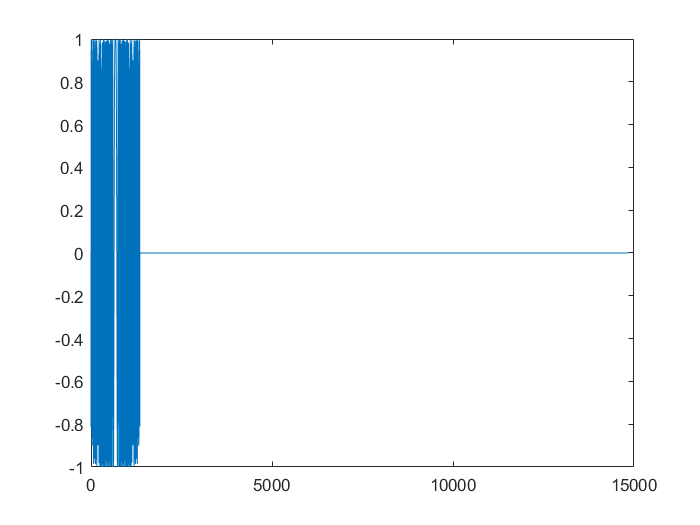

% 每一行脉冲都需要进行一次频域匹配滤波 这里做的是频域的匹配滤波！！！
% 这叫脉冲压缩



sig_t = rectpuls(t - tp/2, tp).*exp(1j * pi * K * (t - tp/2).^2);
figure
plot(R_x, real(sig_t))

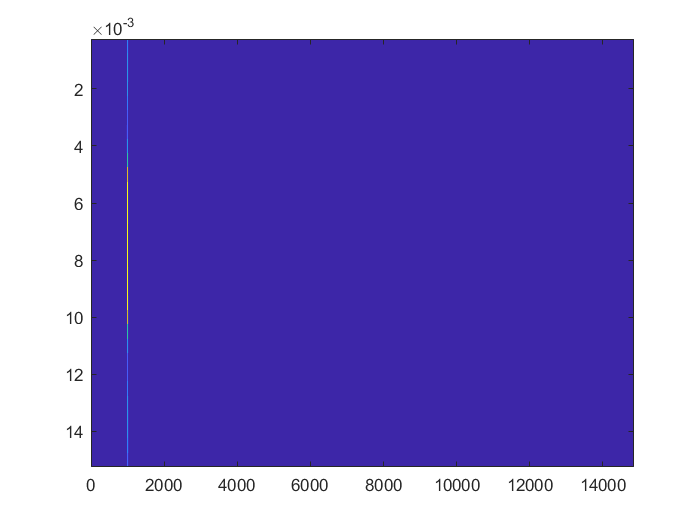

ht = conj(fliplr(sig_t));

% Hanning 窗脉冲匹配滤波距离
win_l = length(sig_r);
h = zeros(1, win_l); % 窗函数的向量

win = hamming(win_l)'; % 窗口
h_win = ht.*win; % 对滤波器进行加窗处理
sig_tf = fft(h_win);
sr_fil = zeros(N, N_smp);
for i = 1:N
    sr_fil(i, :) = ifft(fft(sig_r(i, :)).*sig_tf);
end
figure(3)
image(R_x, t_y, abs(sr_fil));

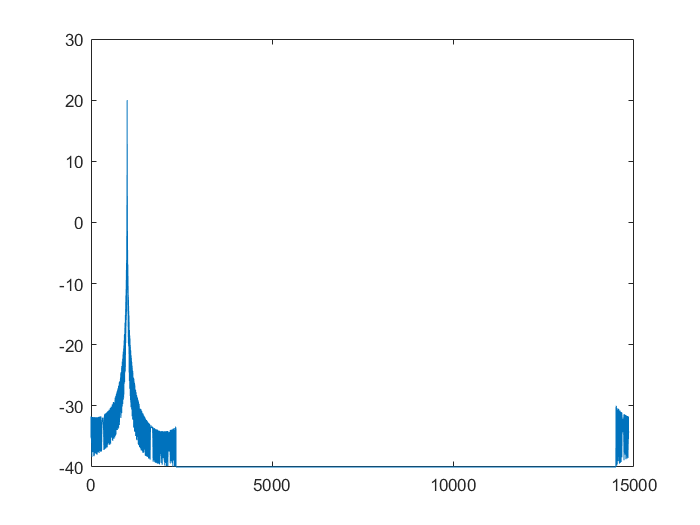

figure(4)
plot(R_x, norm_dbv((sr_fil(1, :)))+20); % 通过匹配滤波器后的单个脉冲信号

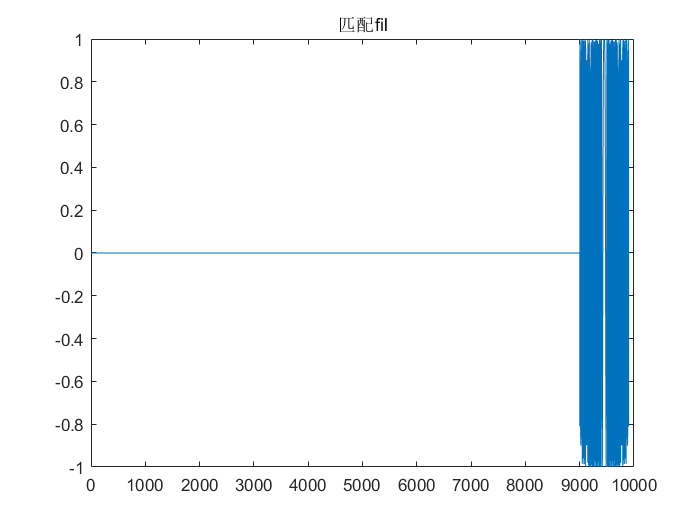


% 做一次时域的匹配滤波
ht = conj(fliplr(sig_t));
figure
plot(real(ht)); title('匹配fil');

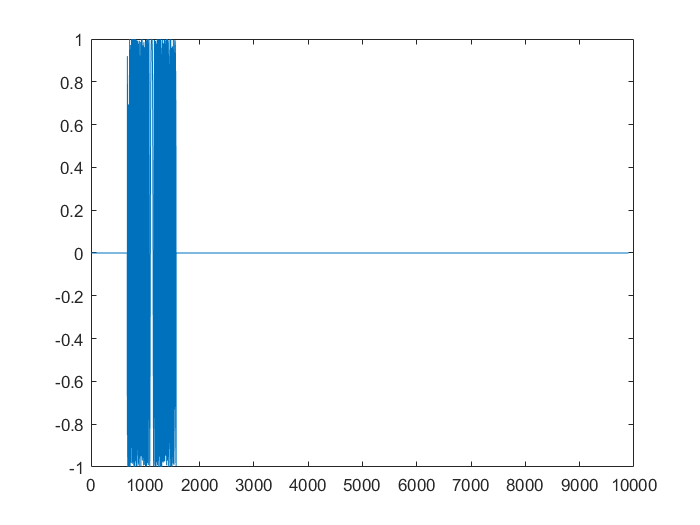

figure
plot(real(sig_r(1, :)));

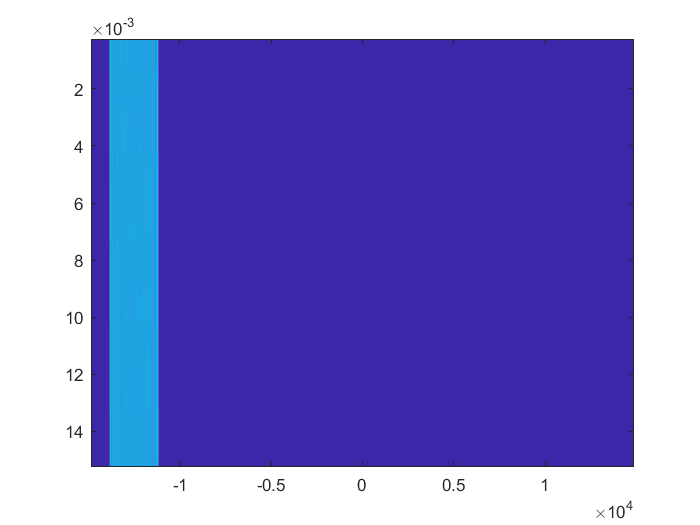

t_time_fil = linspace(-(smp_mc*tp + tp), (smp_mc*tp + tp), 2 * N_smp - 1); % 要变换t
% t_time_fil = linspace(0, smp_mc*tp + tp, 2*N_smp - 1);
R_x_time_fil = c * t_time_fil / 2;
sr_fil = [];
for i = 1:N
    sr_fil(i, :) = xcorr(sig_r(i, :), ht); % 这里成了2N - 1
end
figure(5)
image(R_x_time_fil, t_y, abs(sr_fil));

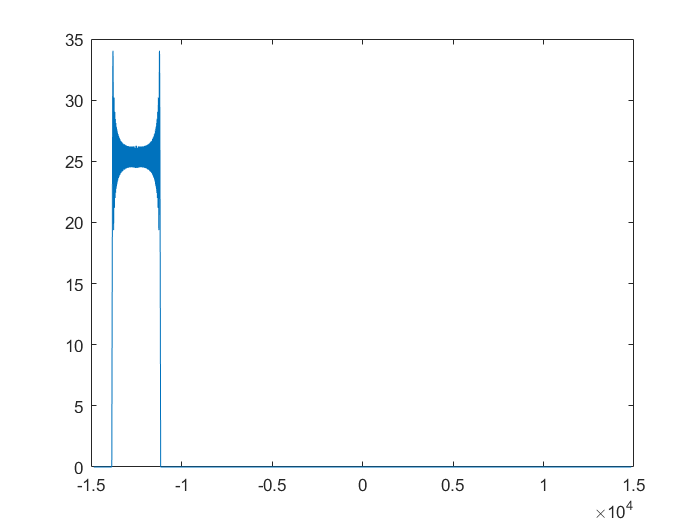

figure(6)
plot(R_x_time_fil, abs(sr_fil(1, :))); % 通过匹配滤波器后的单个脉冲信号

% 结论就是在增加了速度后，输出会有偏移，这个偏移量是由多普勒频率造成的 加窗函数预计主瓣和副瓣之间的区别会更大


% 时域的线性卷积会造成时间上的扩大


## 速度补偿

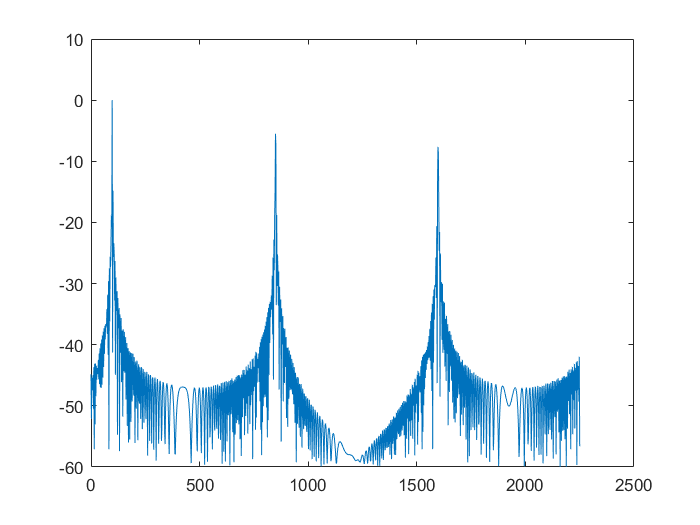

PRF = 2e3; % 脉冲重复频率
PRI = 1/PRF; % 脉冲重复间隔
fs = 80e6; % 采样率
Bw = 40e6; % 带宽
tp = 5e-6; % 脉宽
K = Bw / tp; % 调制斜率
c = 3e8;
% N = 6/60 * PRF; % 根据时长(s)来确定脉冲个数
N = 30; % 脉冲数定为30个 
smp_mc = 2; % 单次采样时间的比脉宽
t_init = 0:1/fs:smp_mc*tp + tp;
t = 0 + PRI:1/fs:smp_mc*tp + tp + PRI; % 单次采样的时间长度为21个脉宽 (一个PRI可以包含100个脉冲，占空比为1%)
N_smp = length(t); % 采样点个数
Rmax = smp_mc * tp * c / 2; % 本程序可以探测的最远距离！！ 实际应该是 1/2 * c * PRI
R_x = c * t_init / 2;

R0 = 100;
v = 50;

delta_tau = 2 * (R0 - v.*t) / c;
sig_v = exp(1j * pi * K * (t - tp/2 - delta_tau).^2);
sig_v_s = exp(1j * pi * K * (t - tp/2 - (2 * R0 /c)).^2);

% 匹配滤波
sig_t = exp(1j * pi * K * (t - tp/2).^2);
ht = conj(fliplr(sig_t));
sig_tf = (fft(ht));
sig_v_fil = ifft(fft(sig_v).*sig_tf);
sig_v_s_fil = ifft(fft(sig_v_s).*sig_tf);
figure
title('未速度补偿的波形')
plot(R_x, norm_dbv(sig_v_fil));

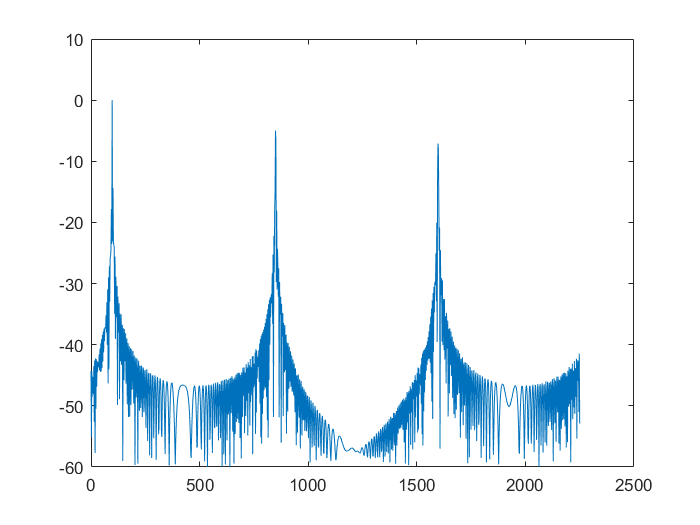

figure
plot(R_x, norm_dbv(sig_v_s_fil))

% 速度补偿
ht_v = ht .* exp(1j * 4 * pi * v .* (f0 / c));
sig_tf = fft(ht_v);
sig_v_fil_v = ifft(fft(sig_v).*sig_tf);
figure
title('速度补偿波形')
plot(R_x, norm_dbv(sig_v_fil_v))

## 速度补偿2

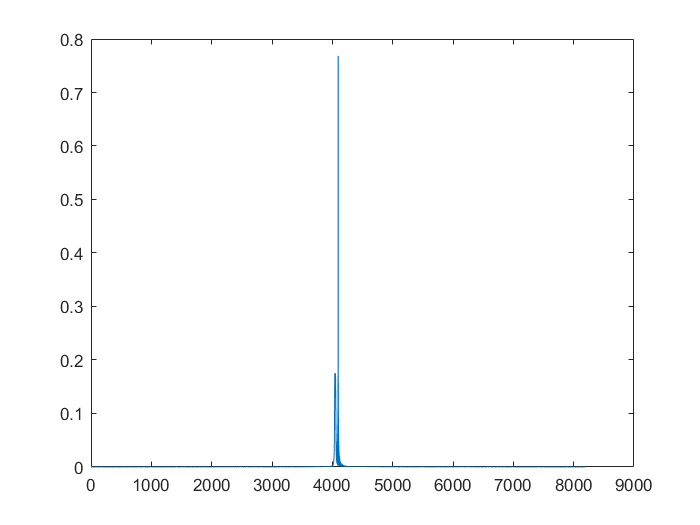

% 根据分析，在实际雷达处理信号时，会对每一个脉冲进行一次采样，并且一个距离门采样单点信号 先按这个思路做一下
% 假设雷达接收机可以分辨出不同目标反射回波的第一个信号
% step1：生成回波信号
N_puls = 1024*4; % 处理的脉冲数
R = [100, 3000, 5000]; % 三个目标的初始距离
N_tgt = 3;
V = [90, 0, 0];
RCS = [1, 1, 2];
sig_rec = zeros(1, N_puls); % 处理的最终信号
sig_rec_I = zeros(1, N_puls); % 处理的最终信号
sig_rec_Q = zeros(1, N_puls); % 处理的最终信号
for i_tgt = 1:N_tgt
    ii = 0;
    for i_puls = 1:N_puls
        ii = ii + 1;
        sig_rec(ii) = sig_rec(ii) + sqrt(RCS(i_tgt)) * ...
                          exp(1j * 2 * pi * f0 * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)) +  1j * pi * K * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)).^2);
        sig_rec_I(ii) = sig_rec_I(ii) + cos(2 * pi * f0 * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)) +  pi * K * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)).^2);
        sig_rec_Q(ii) = sig_rec_Q(ii) + sin(2 * pi * f0 * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)) +  pi * K * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)).^2);
    end
end
% % 观察一次
% plot(real(sig_rec))
% plot(abs(fftshift(fft(sig_rec))))% 脉冲数 2048没有问题可以得到相应的频率分辨率
% 脉冲压缩
sig_rec_IQ = zeros(1, 2 * N_puls);
sig_rec_IQ(1:N_puls) = sig_rec_I + 1j * sig_rec_Q;
sig_rec_IQ(N_puls + 1:2*N_puls) = 0 + 0j;
sig_rec_IQ_time = fftshift(ifft(sig_rec_IQ));
plot(abs(sig_rec_IQ_time));

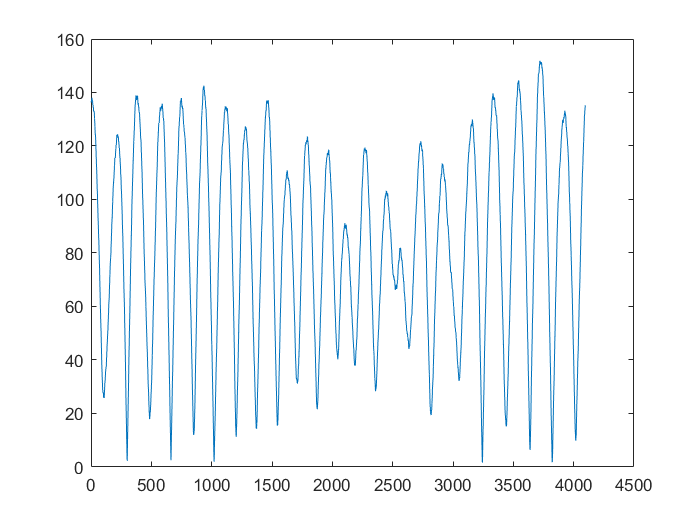

% 傅里叶逆变换

t = linspace(0, N_puls*PRI, N_puls);
sig_t = exp(1j * 2 * pi * f0 * t + 1j * pi * K * t.^2);
% 匹配滤波器需要重新设计 是一个没有时延的回波信号


ht = conj(fliplr(sig_t));
Hf = fft(ht);
sig_rec_fli = ifft(fft(sig_rec).*Hf);
plot(abs(sig_rec_fli))

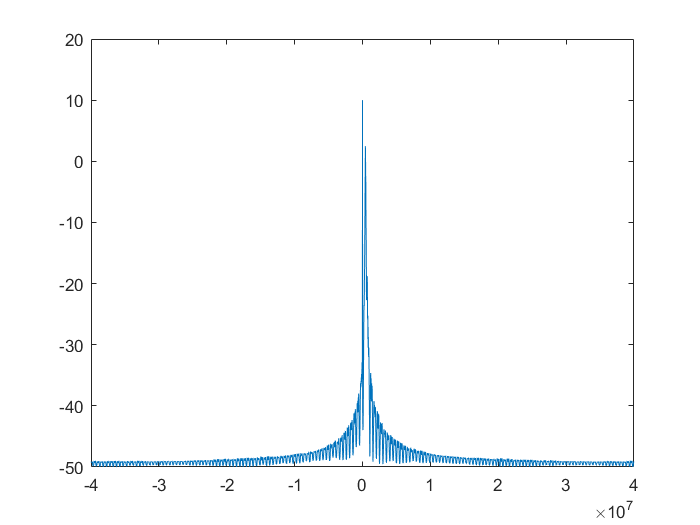

f = (-N_puls/2:N_puls/2 - 1)*fs/N_puls;
plot(f, norm_dbv(abs(fftshift(fft(sig_rec_fli)))) + 10)

Ru = c/2/Bw;
delx_meter = Ru / N_puls;
x_meter = 0:delx_meter:Ru - delx_meter;
plot(f, norm_dbv(abs(fftshift(fft(sig_rec_fli)))) + 10);


    
% exp(1j * 2 * pi * f0 * (2 * R(i_tgt) / c + 1j * 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)) +  1j * pi * K * (2 * R(i_tgt) / c + 2 * (V(i_tgt) / c) * ((i_puls - 1)*PRI + 2 * R(i_tgt) / c)).^2);


## 加窗函数分析

## dbv

function out = norm_dbv(in)
out = mapminmax(abs(in), 0, 1);
out = 20 * log10(out + 1e-3);
end
